**ФЕДЕРАЛЬНОЕ АГЕНТСТВО ЖЕЛЕЗНОДОРОЖНОГО ТРАНСПОРТА **

Федеральное государственное бюджетное образовательное учреждение высшего образования

**«Петербургский государственный университет путей сообщения **

**Императора Александра ****I****»**

**(ФГБОУ ВО ПГУПС)**

Факультет «Транспортные и энергетические системы»

Кафедра «Электрическая тяга»

Специальность 25.05.03 «Подвижной состав железных дорог»

Специализация «Электрический транспорт»

Дисциплина «Компьютерное моделирование электрооборудования ЭПС»

**Отчет по ТЗ №1**

**«Разработка математической модели коллекторного ТЭД  (последовательное/независимое возбуждение)»**

**Вариант №5**

 **Выполнил студент**

 **Курс: 4**

**Группа: ПС-003**

Дулепов И.Г.

                                                                                     ______________      

                                                                                      (Дата, подпись)   

  **Руководитель                                                                                                                                                           **Сычугов А.Н.                                                                                                                                   

                                                                                    ______________      

                                                                                      (Дата, подпись)                                                        

Санкт-Петербург 

2024

**Типовая задача №1.  Моделирования коллекторного ТЭД:**

## **Введение**

**Цель работы:** Построение математической модели двигателя заданного типа в соответствии с исходными данными, построение скоростных и тяговых характеристик машины постоянного тока на основе смоделированных данных в диапазоне коэффициента заполнения 0,1-1,0 и для двух ступеней ослабления возбуждения.

## **1. Задание исходных данных (для двигателя ТЭД-3У) общие данные для последовательного и независимого возбуждения ТЭД:**

### **1.1. Задание параметров для снятия скоростных и тяговых характеристик двигателя:**

Напряжение на коллекторе, В:

Udnom.voltage = 750;

Ток якоря (Iян=Imax), А:

Imax.current = 350;

Начальная и максимальная скорость движения, км/ч.:

Vnach.speed = 120;
Vmax.speed = Vnach.speed*(0.9);

Ступень ослабления возбуждения поля и коэффициент заполнения:

Stup_osl_polya.step = 0;
lamda.coefficient = 0.1;

###  **1.2. Задание параметров блоков ТЭД в соответствии таблицей характеристик двигателя ТЭД-3У методических указаний:**

Номинальные данные и конструкционные параметры ТЭД-3У:

n_vr = 800; %Частота вращения, об/мин
p_v = 2; %Число пар полюсов
w = 58; %Число витков полюсной катушки
a = 2; %Число пар параллельных ветвей якоря
sigma = 1.25; %Коэффициент рассеяния
C = 17.5; %Конструкционный коэффициент обмоток
C_v = 188.4; %Приведенный конструкционный коэффициент,1/с(км/ч)
Epsilon = 3.44; % Передаточное число тягового редуктора

Геометрические размеры остова, м:

h_0 = 0.3; %осевая длина,
s_0 = 0.015; %толщина по радиусу
l_m = 0.06; %длина полюсной дуги

Геометрические размеры полюсов, м:

l_p = 0.6; %длина
b_p = 0.05; %ширина
h_p = 0.75; %высота

Параметры сопротивления и индуктивности обмотки якоря, Ом, Гн:

RaLa.Res = 0.05; %Сопротивление якоря, доп. полюсов, компенсационной обмотки, Ом

Величину индуктивности обмотки якоря вычисляем по номинальным  значениям напряжения Uдн, тока Iян, частоты вращения nн , числу пар параллельных ветвей обмоток якоря ТЭД:

RaLa.Ind = (0.25*(Udnom.voltage*60))/(Imax.current*a*2*3.14*n_vr)

Параметры сопротивления и индуктивности обмотки возбуждения, Ом, Гн:

ReLe.Res = 0.1;

Отсюда напряжение обмотки возбуждения, В:

Udnom1.voltage = Imax.current*ReLe.Res;

Величину индуктивности рассеяния обмотки возбуждения ТЭД компьютерной модели вычисляем для коэффициента линеаризации Кф, соответствующего расчетному току возбуждения по формуле, Гн

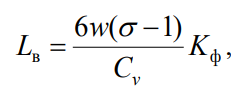

Расчет коэффициента наклона Кф, Ом/км/ч, линеаризующего отрезка характеристики намагничивания СvФ(Iв) тяговых электродвигателей  выполняем для тока возбуждения Iв=β0*Iуст в диапазоне его изменения ∆Iв =100А по формуле:

Для расчета постоянной времени вихревых токов Tвх, а также индуктивности обмоток возбуждения с учетом степени насыщения магнитопровода строим по численным значениям из табл. 4 методических указаний характеристику намагничивания  СvФ(Iв) ТЭД и выполняем ее линеаризацию.

I_ust = 250; %Ток ТЭД в расчетном режиме
Iv = [25 50 100 150 175 200 250 300 350 400 450];
Cvf = [5 7.7 12.1 14.3 15 15.5 16.5 17.1 17.6 17.9 18.2];
beta0 = 0.98; %коэффициент ослабления возбуждения
I_v = (250*0.98);
xI_v = [I_v I_v];

RaLa = struct with fields:
    Res: 0.0500
    Ind: 0.0032


yI_v = [0 16.43];
xI_vmin = [I_v-50 I_v-50];
yI_vmin = [0 15.4];
xI_vmax = [I_v+50 I_v+50];
yI_vmax = [0 17.05];
xCvf0 = [0 I_v];
yCvf0 = [16.43 16.43];
xCvf0min = [0 I_v-50];
yCvf0min = [15.4 15.4];
xCvf0max = [0 I_v+50];
yCvf0max = [17.05 17.05];
plot (Iv,Cvf,xI_v,yI_v,xI_vmin,yI_vmin,xI_vmax,yI_vmax,xCvf0,yCvf0,xCvf0min,yCvf0min,xCvf0max,yCvf0max)
grid("minor");
xlabel('Iв, А');
ylabel('CvФ0, В/км/ч');
title('Характерисика намагничивания ТЭД');

Из полученной характеристики выдно, что величина ∆СvФ равна и коэффициент наклона Кф равен:

deltaCvF = 17.05-15.4;
deltaI_v = 100;
K_f = deltaCvF/deltaI_v;

Отсюда величина индуктивности рассеяния обмотки возбуждения ТЭД:

ReLe.Ind = ((6*w*(sigma-1))/C_v)*K_f

Сопротивление шунтирующих резисторов постоянного шунтирования и двух ступеней ослабления возбуждения ТЭД с коэффициентами β0=0,98 β1=0,75 и  β2=0,5, Ом:

beta1 = 0.75;
beta2 = 0.5;
R0sh = ReLe.Res*(beta0/(1-beta0));
R1sh = ReLe.Res*(beta1/(1-beta1));
R2sh = ReLe.Res*(beta2/(1-beta2));

Сопротивление резистора в цепи 1-й ступени ослабления возбуждения компьтерной модели ТЭД Rsh1 = R1ш - R2ш, сопротивление резистора 2-й ступени ослабления возбуждения Rsh2 = R2ш.

Rsh0.Res = R0sh
Rsh1.Res = R1sh-R2sh;
Rsh2.Res = R2sh;

Величину проводимости контура вихревых токов gвх , 1/Ом, вычисляем по геометрическим размерам магнитопровода ТЭД:

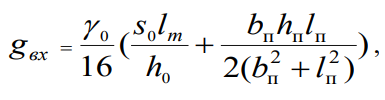

gamma_0 = 7.15*10^6; %удельная проводимость стали остова
g_vh = (gamma_0/16)*(((s_0*l_m)/h_0)+((b_p*h_p*l_p)/(2*((b_p^2)+(l_p^2)))));

Постоянная времени контура вихревых токов ТЭД Tвх, с:

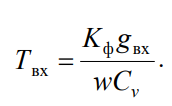

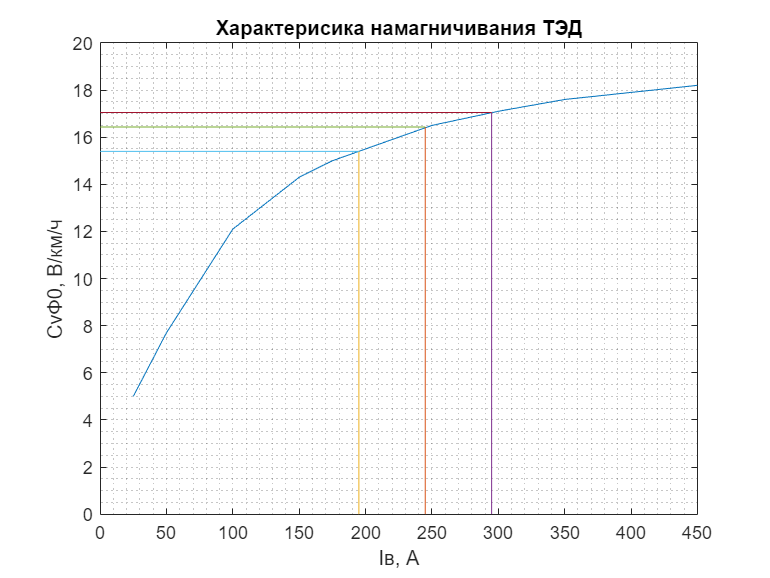

Tokivx.time = ((K_f*g_vh)/(w*C_v))

Коэффициент усиления дифференцирующего звена определяется числом витков полюсных катушек ТЭД, с(км/ч): 

Es.coefficient = (6*w)/C_v

В блоке n-D Lookup Table задаем параметры характеристики намагничивания ТЭД виде массива данных:

CF.currentvozb = [0 25 50 100 150 175 200 250 300 350 400 450];
CF.CvF = [0 5 7.7 12.1 14.3 15 15.5 16.5 17.1 17.6 17.9 18.2];

## ** 2. Моделирование ТЭД последовательного возбуждения:**

На рисунках 1-2 представлена математическая модель двигателя постоянного тока с последовательным возбуждением:

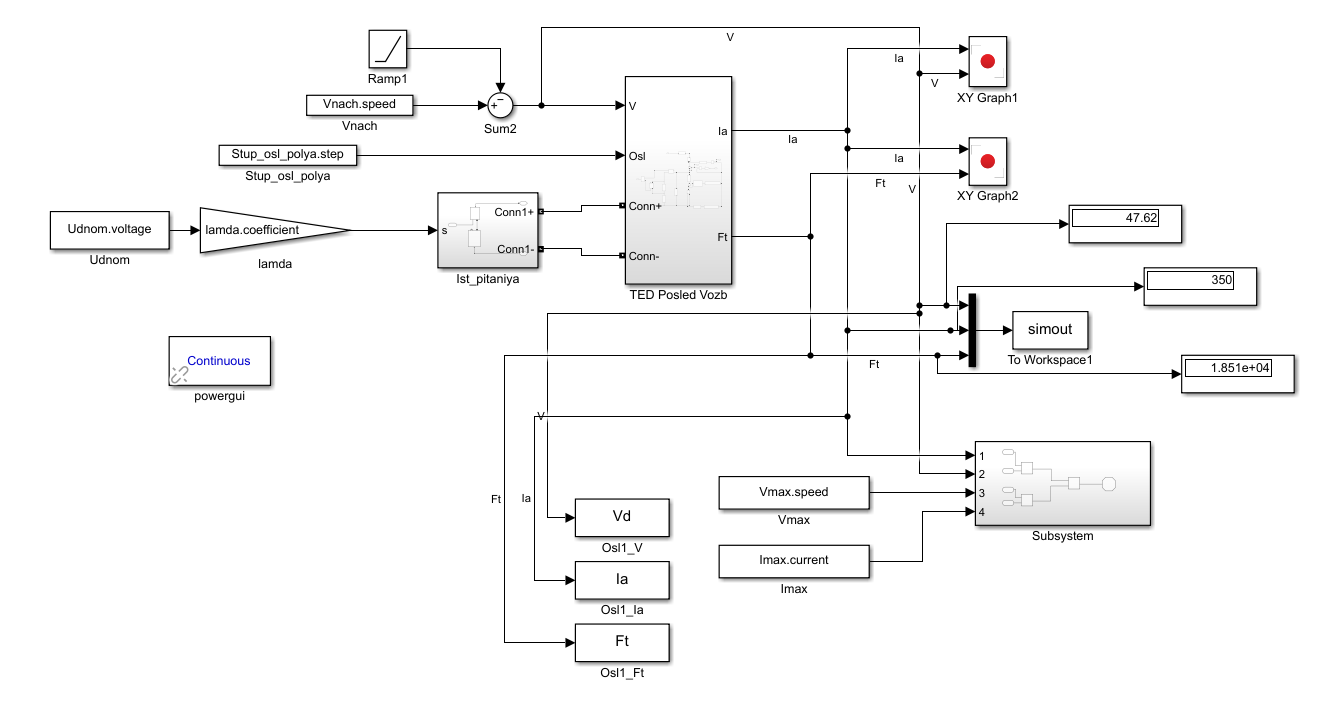

Рисунок 1. Модель двигателя постоянного тока с последовательным возбуждением, с блоками для проведения исследований

Рисунок 2. Подсистема модели двигателя постоянного тока с последовательным возбуждением

Произсводим измерение скорости и силы тяги ТЭД в зависимости от тока якоря при различном значении коэффициента заполнения lamda:

Шаг измерения по скорости (изменение на 1 изменяет скорость на 0,1):

step.measurements = 5;

ReLe = struct with fields:
    Res: 0.1000
    Ind: 0.0076


Выполняем построение скоростной и тяговой характеристики ТЭД,  меняя коэффициент заполнения lamda в диапазоне от 0,1 до 1 с шагом 0,1. 

for Osl = 0
    Stup_osl_polya.step = Osl;
for lambda = 0.1
lamda.coefficient = lambda;
sim 'IVVAN.slx'
op1 = (simout.signals.values);
end

Rsh0 = struct with fields:
    Res: 4.9000


for lambda = 0.2
lamda.coefficient = lambda;
sim 'IVVAN.slx'
op2 = (simout.signals.values);
end
for lambda = 0.3
lamda.coefficient = lambda;
sim 'IVVAN.slx'
op3 = (simout.signals.values);

Tokivx = struct with fields:
    time: 0.0230


end
for lambda = 0.4
lamda.coefficient = lambda;

Es = struct with fields:
    coefficient: 1.8471


sim 'IVVAN.slx'
op4 = (simout.signals.values);
end
for lambda = 0.5
lamda.coefficient = lambda;
sim 'IVVAN.slx'
op5 = (simout.signals.values);
end
for lambda = 0.6
lamda.coefficient = lambda;
sim 'IVVAN.slx'
op6 = (simout.signals.values);
end
for lambda = 0.7
lamda.coefficient = lambda;
sim 'IVVAN.slx'
op7 = (simout.signals.values);
end
for lambda = 0.8
lamda.coefficient = lambda;
sim 'IVVAN.slx'
op8 = (simout.signals.values);
end
for lambda = 0.9
lamda.coefficient = lambda;
sim 'IVVAN.slx'
op9 = (simout.signals.values);
end
for lambda = 1
lamda.coefficient = lambda;
sim 'IVVAN.slx'
op10 = (simout.signals.values);
end
end

Выполняем построение скоростной и тяговой характеристик ТЭД при двух ступенях ослабления поля βо1=0,75 и βо2=0,5:

step.measurements = 10;
for Osl = 1
    Stup_osl_polya.step = Osl;
for lambda = 1
    lamda.coefficient = lambda;
sim 'IVVAN.slx'
opOsl1 = (simout.signals.values);
end
end
for Osl = 2
    Stup_osl_polya.step = Osl;
for lambda = 1
    lamda.coefficient = lambda;
sim 'IVVAN.slx'
opOsl2 = (simout.signals.values);
end
end


Скоростные характеристики ТЭД:

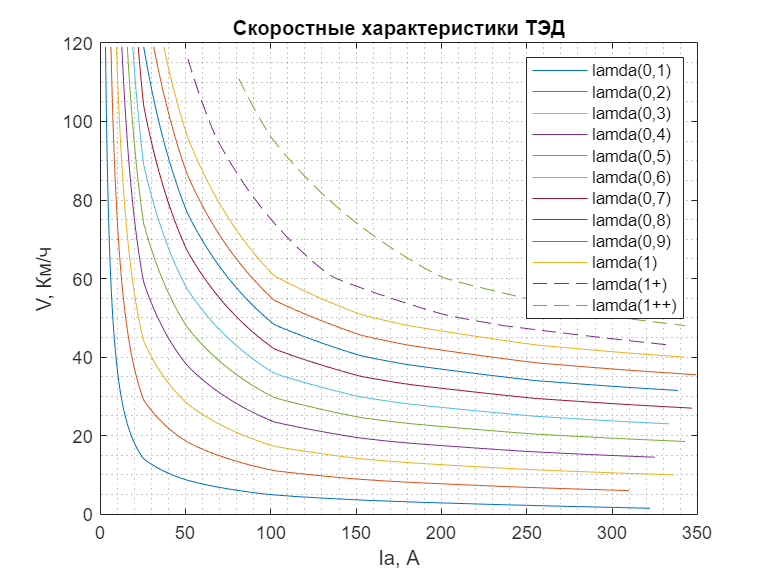

Ia1 = op1 (3:end, 2);
V1 = op1 (3:end, 1);
Ia2 = op2 (3:end, 2);
V2 = op2 (3:end, 1);
Ia3 = op3 (3:end, 2);
V3 = op3 (3:end, 1);
Ia4 = op4 (3:end, 2);
V4 = op4 (3:end, 1);
Ia5 = op5 (3:end, 2);
V5 = op5 (3:end, 1);
Ia6 = op6 (3:end, 2);
V6 = op6 (3:end, 1);
Ia7 = op7 (3:end, 2);
V7 = op7 (3:end, 1);
Ia8 = op8 (3:end, 2);
V8 = op8 (3:end, 1);
Ia9 = op9 (3:end, 2);
V9 = op9 (3:end, 1);
Ia10 = op10 (3:end, 2);
V10 = op10 (3:end, 1);
IaOsl1 = opOsl1 (5:end, 2);
VOsl1 = opOsl1 (5:end, 1);
IaOsl2 = opOsl2 (10:end, 2); 
VOsl2 = opOsl2 (10:end, 1);
plot(Ia1,V1,Ia2,V2,Ia3,V3,Ia4,V4,Ia5,V5,Ia6,V6,Ia7,V7,Ia8,V8,Ia9,V9,Ia10,V10,IaOsl1,VOsl1,'--',IaOsl2,VOsl2,'--')
grid("minor");
xlabel('Ia, А');
ylabel('V, Км/ч');
title('Скоростные характеристики ТЭД');
legend(["lamda(0,1)","lamda(0,2)","lamda(0,3)","lamda(0,4)","lamda(0,5)","lamda(0,6)","lamda(0,7)","lamda(0,8)","lamda(0,9)","lamda(1)","lamda(1+)","lamda(1++)"])
xlim([0 350])

Тяговые характеристики ТЭД:

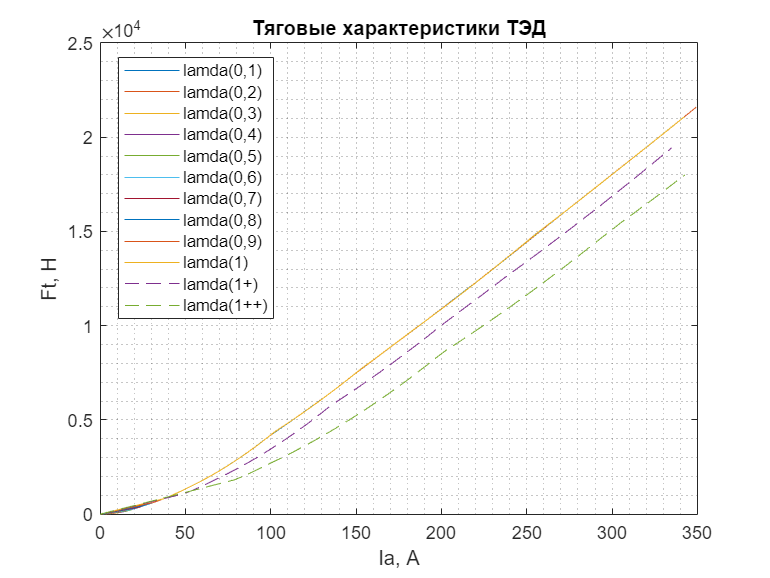

Ia1 = op1 (1:end, 2);
Ft1 = op1 (1:end, 3);
Ia2 = op2 (1:end, 2);
Ft2 = op2 (1:end, 3);
Ia3 = op3 (1:end, 2);
Ft3 = op3 (1:end, 3);
Ia4 = op4 (1:end, 2);
Ft4 = op4 (1:end, 3);
Ia5 = op5 (1:end, 2);
Ft5 = op5 (1:end, 3);
Ia6 = op6 (1:end, 2);
Ft6 = op6 (1:end, 3);
Ia7 = op7 (1:end, 2);
Ft7 = op7 (1:end, 3);
Ia8 = op8 (1:end, 2);
Ft8 = op8 (1:end, 3);
Ia9 = op9 (1:end, 2);
Ft9 = op9 (1:end, 3);
Ia10 = op10 (1:end, 2);
Ft10 = op10 (1:end, 3);
IaOsl1 = opOsl1 (1:end, 2);
FtOsl1 = opOsl1 (1:end, 3);
IaOsl2 = opOsl2 (1:end, 2);
FtOsl2 = opOsl2 (1:end, 3);
plot(Ia1,Ft1,Ia2,Ft2,Ia3,Ft3,Ia4,Ft4,Ia5,Ft5,Ia6,Ft6,Ia7,Ft7,Ia8,Ft8,Ia9,Ft9,Ia10,Ft10,IaOsl1,FtOsl1,'--',IaOsl2,FtOsl2,'--')
grid("minor");
xlabel('Ia, А');
ylabel('Ft, Н');
title('Тяговые характеристики ТЭД');
legend(["lamda(0,1)","lamda(0,2)","lamda(0,3)","lamda(0,4)","lamda(0,5)","lamda(0,6)","lamda(0,7)","lamda(0,8)","lamda(0,9)","lamda(1)","lamda(1+)","lamda(1++)"])
xlim([0 350])
ylim([0 25000])
legend("Position",[0.15416,0.44984,0.20179,0.45119])

Переносим данные расчетов из рабочего окна Matlab в Live Editor,  заполняем соответствующую таблицу 1.

OP_Step = 20; %изменение шага таблицы по скорости движения V, км/ч.
OP_lambda01 = repelem (0.1, height(op1(1:OP_Step:end, 1))).'; %массивы данных для коэффициента заполения от 0,1 до 10
OP_lambda02 = repelem (0.2, height(op2(1:OP_Step:end, 1))).'; %для опытов с последовательным возбуждением ТЭД
OP_lambda03 = repelem (0.3, height(op3(1:OP_Step:end, 1))).';
OP_lambda04 = repelem (0.4, height(op4(1:OP_Step:end, 1))).';
OP_lambda05 = repelem (0.5, height(op5(1:OP_Step:end, 1))).';
OP_lambda06 = repelem (0.6, height(op6(1:OP_Step:end, 1))).';
OP_lambda07 = repelem (0.7, height(op7(1:OP_Step:end, 1))).';
OP_lambda08 = repelem (0.8, height(op8(1:OP_Step:end, 1))).';
OP_lambda09 = repelem (0.9, height(op9(1:OP_Step:end, 1))).';
OP_lambda10 = repelem (1, height(op10(1:OP_Step:end, 1))).';
OP_lambda100 = repelem (1, height(opOsl1(1:OP_Step:end, 1))).';
OP_lambda1000 = repelem (1, height(opOsl2(1:OP_Step:end, 1))).';
OP_lambdaPosled = [OP_lambda01.' OP_lambda02.' OP_lambda03.' OP_lambda04.' OP_lambda05.' OP_lambda06.' OP_lambda07.' OP_lambda08.' OP_lambda09.' OP_lambda10.' OP_lambda100.' OP_lambda1000.'].';
OP_VPosled = [op1(1:OP_Step:end, 1).' op2(1:OP_Step:end, 1).' op3(1:OP_Step:end, 1).' op4(1:OP_Step:end, 1).' op5(1:OP_Step:end, 1).' op6(1:OP_Step:end, 1).' op7(1:OP_Step:end, 1).' op8(1:OP_Step:end, 1).' op9(1:OP_Step:end, 1).' op10(1:OP_Step:end, 1).' opOsl1(1:OP_Step:end, 1).' opOsl2(1:OP_Step:end, 1).'].';
OP_IaPosled = [op1(1:OP_Step:end, 2).' op2(1:OP_Step:end, 2).' op3(1:OP_Step:end, 2).' op4(1:OP_Step:end, 2).' op5(1:OP_Step:end, 2).' op6(1:OP_Step:end, 2).' op7(1:OP_Step:end, 2).' op8(1:OP_Step:end, 2).' op9(1:OP_Step:end, 2).' op10(1:OP_Step:end, 2).' opOsl1(1:OP_Step:end, 2).' opOsl2(1:OP_Step:end, 2).'].';
OP_FtPosled = [op1(1:OP_Step:end, 3).' op2(1:OP_Step:end, 3).' op3(1:OP_Step:end, 3).' op4(1:OP_Step:end, 3).' op5(1:OP_Step:end, 3).' op6(1:OP_Step:end, 3).' op7(1:OP_Step:end, 3).' op8(1:OP_Step:end, 3).' op9(1:OP_Step:end, 3).' op10(1:OP_Step:end, 3).' opOsl1(1:OP_Step:end, 3).' opOsl2(1:OP_Step:end, 3).'].';
T_Posled = table(OP_lambdaPosled, OP_VPosled, OP_IaPosled, OP_FtPosled);
T_Posled.Properties.VariableNames = ["lambda", "V, км/ч", "Ia, А", "Ft, Н"];
disp(T_Posled);

    lambda    V, км/ч    Ia, А     Ft, Н 
    ______    _______    ______    ______

     0.1        120           0         0
     0.1        110      3.4182    8.0786
     0.1        100      3.7575    9.7618
     0.1         90      4.1715    12.031
     0.1         80       4.688    15.195
     0.1         70      5.3506    19.794
     0.1         60      6.2313    26.845
     0.1         50      7.4589    38.464
     0.1         40      9.2889     59.65
     0.1         30      12.309    104.73
     0.1         20      18.236    229.84
     0.1         10      42.343    1012.5
     0.2        120           0         0
     0.2        110      6.8732    32.664
     0.2        100      7.5554    39.469
     0.2         90      8.3879    48.646
     0.2         80      9.4266    61.439
     0.2         70      10.759    80.031
     0.2         60    

## **3. Моделирование ТЭД независимого возбуждения:**

На рисунках 3-4 представлена математическая модель двигателя постоянного тока с независимым возбуждением:

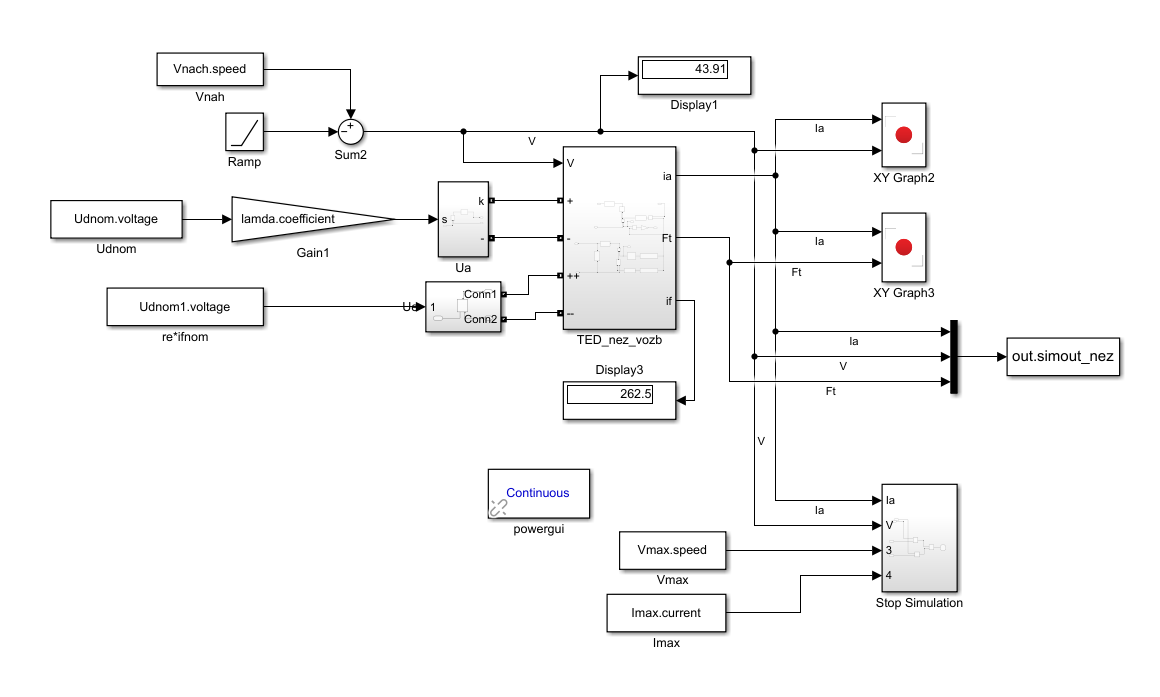

Рисунок 3. Модель двигателя постоянного тока с независимым возбуждением, с блоками для проведения исследований

Рисунок 4. Подсистема модели двигателя постоянного тока с независимым возбуждением

Произсводим измерение скорости и силы тяги ТЭД в зависимости от тока якоря при различном значении коэффициента заполнения lamda:

Шаг измерения по скорости (изменение на 1 изменяет скорость на 0,1):

step.measurementsnez = 0.9;

Imax.current = 350;
Udnom1.voltage = Imax.current*ReLe.Res;
V_nez = 120;
for lambda_nez = 0.1
lamda.coefficient = lambda_nez;
Vnach.speed = V_nez;
sim 'Nezavisimoe.slx';
op1_nez = (ans.simout_nez.signals.values);
end
for lambda_nez = 0.2
lamda.coefficient = lambda_nez;
Vnach.speed = V_nez;
sim 'Nezavisimoe.slx';
op2_nez = (ans.simout_nez.signals.values);
end
for lambda_nez = 0.3
lamda.coefficient = lambda_nez;
Vnach.speed = V_nez;
sim 'Nezavisimoe.slx';
op3_nez = (ans.simout_nez.signals.values);
end
for lambda_nez = 0.4
lamda.coefficient = lambda_nez;
Vnach.speed = V_nez;
sim 'Nezavisimoe.slx';
op4_nez = (ans.simout_nez.signals.values);
end
for lambda_nez = 0.5
lamda.coefficient = lambda_nez;
Vnach.speed = V_nez;
sim 'Nezavisimoe.slx';
op5_nez = (ans.simout_nez.signals.values);
end
for lambda_nez = 0.6
lamda.coefficient = lambda_nez;
Vnach.speed = V_nez;
sim 'Nezavisimoe.slx';
op6_nez = (ans.simout_nez.signals.values);
end
for lambda_nez = 0.7
lamda.coefficient = lambda_nez;
Vnach.speed = V_nez;
sim 'Nezavisimoe.slx';
op7_nez = (ans.simout_nez.signals.values);
end
for lambda_nez = 0.8
lamda.coefficient = lambda_nez;
Vnach.speed = V_nez;
sim 'Nezavisimoe.slx';
op8_nez = (ans.simout_nez.signals.values);
end
for lambda_nez = 0.9
lamda.coefficient = lambda_nez;
Vnach.speed = V_nez;
sim 'Nezavisimoe.slx';
op9_nez = (ans.simout_nez.signals.values);
end
for lambda_nez = 1
lamda.coefficient = lambda_nez;
Vnach.speed = V_nez;
sim 'Nezavisimoe.slx';
op10_nez = (ans.simout_nez.signals.values);
end

Выполняем построение скоростной и тяговой характеристик ТЭД при двух ступенях ослабления поля βо1=0,75 и βо2=0,5:

V_nez = 120;
for lambda_nez = 1
lamda.coefficient = lambda_nez;
Vnach.speed = V_nez;
Osl1_nez = 0.75;
Udnom1.voltage = Imax.current*ReLe.Res*Osl1_nez;
sim 'Nezavisimoe.slx';
opOsl1_nez = (ans.simout_nez.signals.values);
end
for lambda_nez = 1
lamda.coefficient = lambda_nez;
Vnach.speed = V_nez;
Osl2_nez = 0.5;
Udnom1.voltage = Imax.current*ReLe.Res*Osl2_nez;
sim 'Nezavisimoe.slx';
opOsl2_nez = (ans.simout_nez.signals.values);
end

Скоростные характеристики ТЭД:

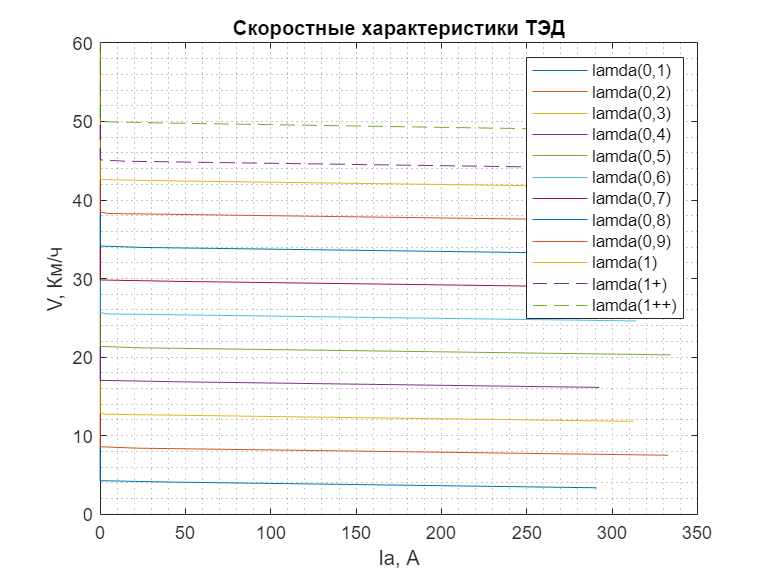

Ia1_nez = op1_nez (4:end, 1);
V1_nez = op1_nez (4:end, 2);
Ia2_nez = op2_nez (4:end, 1);
V2_nez = op2_nez (4:end, 2);
Ia3_nez = op3_nez (4:end, 1);
V3_nez = op3_nez (4:end, 2);
Ia4_nez = op4_nez (4:end, 1);
V4_nez = op4_nez (4:end, 2);
Ia5_nez = op5_nez (4:end, 1);
V5_nez = op5_nez (4:end, 2);
Ia6_nez = op6_nez (4:end, 1);
V6_nez = op6_nez (4:end, 2);
Ia7_nez = op7_nez (4:end, 1);
V7_nez = op7_nez (4:end, 2);
Ia8_nez = op8_nez (4:end, 1);
V8_nez = op8_nez (4:end, 2);
Ia9_nez = op9_nez (4:end, 1);
V9_nez = op9_nez (4:end, 2);
Ia10_nez = op10_nez (4:end, 1);
V10_nez = op10_nez (4:end, 2);
IaOsl1_nez = opOsl1_nez (4:end, 1);
VOsl1_nez = opOsl1_nez (4:end, 2);
IaOsl2_nez = opOsl2_nez (4:end, 1);
VOsl2_nez = opOsl2_nez (4:end, 2);
plot(Ia1_nez,V1_nez,Ia2_nez,V2_nez,Ia3_nez,V3_nez,Ia4_nez,V4_nez,Ia5_nez,V5_nez,Ia6_nez,V6_nez,Ia7_nez,V7_nez,Ia8_nez,V8_nez,Ia9_nez,V9_nez,Ia10_nez,V10_nez,IaOsl1_nez,VOsl1_nez,'--',IaOsl2_nez,VOsl2_nez,'--')
grid("minor");
xlabel('Ia, А');
ylabel('V, Км/ч');
title('Скоростные характеристики ТЭД');
legend(["lamda(0,1)","lamda(0,2)","lamda(0,3)","lamda(0,4)","lamda(0,5)","lamda(0,6)","lamda(0,7)","lamda(0,8)","lamda(0,9)","lamda(1)","lamda(1+)","lamda(1++)"])
xlim([0 350])
ylim([0 60])

Тяговые характеристики ТЭД:

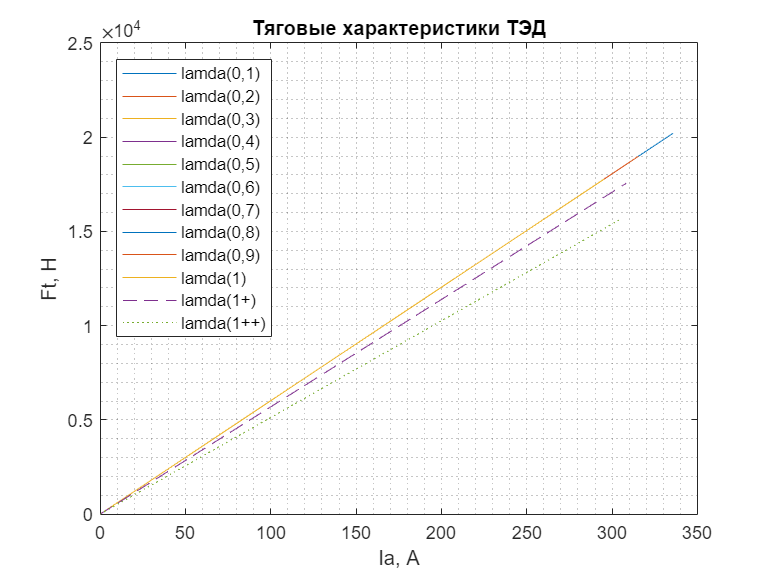

Ia1_nez = op1_nez (1:end, 1);
Ft1_nez = op1_nez (1:end, 3);
Ia2_nez = op2_nez (1:end, 1);
Ft2_nez = op2_nez (1:end, 3);
Ia3_nez = op3_nez (1:end, 1);
Ft3_nez = op3_nez (1:end, 3);
Ia4_nez = op4_nez (1:end, 1);
Ft4_nez = op4_nez (1:end, 3);
Ia5_nez = op5_nez (1:end, 1);
Ft5_nez = op5_nez (1:end, 3);
Ia6_nez = op6_nez (1:end, 1);
Ft6_nez = op6_nez (1:end, 3);
Ia7_nez = op7_nez (1:end, 1);
Ft7_nez = op7_nez (1:end, 3);
Ia8_nez = op8_nez (1:end, 1);
Ft8_nez = op8_nez (1:end, 3);
Ia9_nez = op9_nez (1:end, 1);
Ft9_nez = op9_nez (1:end, 3);
Ia10_nez = op10_nez (1:end, 1);
Ft10_nez = op10_nez (1:end, 3);
IaOsl1_nez = opOsl1_nez (1:end, 1);
FtOsl1_nez = opOsl1_nez (1:end, 3);
IaOsl2_nez = opOsl2_nez (1:end, 1);
FtOsl2_nez = opOsl2_nez (1:end, 3);
plot(Ia1_nez,Ft1_nez,Ia2_nez,Ft2_nez,Ia3_nez,Ft3_nez,Ia4_nez,Ft4_nez,Ia5_nez,Ft5_nez,Ia6_nez,Ft6_nez,Ia7_nez,Ft7_nez,Ia8_nez,Ft8_nez,Ia9_nez,Ft9_nez,Ia10_nez,Ft10_nez,IaOsl1_nez,FtOsl1_nez,'--',IaOsl2_nez,FtOsl2_nez,':')
grid("minor");
xlabel('Ia, А');
ylabel('Ft, Н');
title('Тяговые характеристики ТЭД');
legend(["lamda(0,1)","lamda(0,2)","lamda(0,3)","lamda(0,4)","lamda(0,5)","lamda(0,6)","lamda(0,7)","lamda(0,8)","lamda(0,9)","lamda(1)","lamda(1+)","lamda(1++)"])
xlim([0 350])
ylim([0 25000])
legend("Position",[0.15166,0.4165,0.20107,0.47976])

Переносим данные расчетов из рабочего окна Matlab в Live Editor,  заполняем соответствующую таблицу 2.

OP_StepNez = 1;%изменение шага таблицы по скорости движения V, км/ч.
OP_lambda01 = repelem (0.1, height(op1_nez(end-10:OP_StepNez:end, 2))).'; %массивы данных для коэффициента заполения от 0,1 до 10
OP_lambda02 = repelem (0.2, height(op2_nez(end-10:OP_StepNez:end, 2))).'; %для опытов с независимым возбуждением ТЭД
OP_lambda03 = repelem (0.3, height(op3_nez(end-10:OP_StepNez:end, 2))).';
OP_lambda04 = repelem (0.4, height(op4_nez(end-10:OP_StepNez:end, 2))).';
OP_lambda05 = repelem (0.5, height(op5_nez(end-10:OP_StepNez:end, 2))).';
OP_lambda06 = repelem (0.6, height(op6_nez(end-10:OP_StepNez:end, 2))).';
OP_lambda07 = repelem (0.7, height(op7_nez(end-10:OP_StepNez:end, 2))).';
OP_lambda08 = repelem (0.8, height(op8_nez(end-10:OP_StepNez:end, 2))).';
OP_lambda09 = repelem (0.9, height(op9_nez(end-10:OP_StepNez:end, 2))).';
OP_lambda10 = repelem (1, height(op10_nez(end-10:OP_StepNez:end, 2))).';
OP_lambda100 = repelem (1, height(opOsl1_nez(end-10:OP_StepNez:end, 2))).';
OP_lambda1000 = repelem (1, height(opOsl2_nez(end-10:OP_StepNez:end, 2))).';
OP_lambdaNezavis = [OP_lambda01.' OP_lambda02.' OP_lambda03.' OP_lambda04.' OP_lambda05.' OP_lambda06.' OP_lambda07.' OP_lambda08.' OP_lambda09.' OP_lambda10.' OP_lambda100.' OP_lambda1000.'].';
OP_VNezavis = [op1_nez(end-10:OP_StepNez:end, 1).' op2_nez(end-10:OP_StepNez:end, 1).' op3_nez(end-10:OP_StepNez:end, 1).' op4_nez(end-10:OP_StepNez:end, 1).' op5_nez(end-10:OP_StepNez:end, 1).' op6_nez(end-10:OP_StepNez:end, 1).' op7_nez(end-10:OP_StepNez:end, 1).' op8_nez(end-10:OP_StepNez:end, 1).' op9_nez(end-10:OP_StepNez:end, 1).' op10_nez(end-10:OP_StepNez:end, 1).' opOsl1_nez(end-10:OP_StepNez:end, 1).' opOsl2_nez(end-10:OP_StepNez:end, 1).'].';
OP_IaNezavis = [op1_nez(end-10:OP_StepNez:end, 2).' op2_nez(end-10:OP_StepNez:end, 2).' op3_nez(end-10:OP_StepNez:end, 2).' op4_nez(end-10:OP_StepNez:end, 2).' op5_nez(end-10:OP_StepNez:end, 2).' op6_nez(end-10:OP_StepNez:end, 2).' op7_nez(end-10:OP_StepNez:end, 2).' op8_nez(end-10:OP_StepNez:end, 2).' op9_nez(end-10:OP_StepNez:end, 2).' op10_nez(end-10:OP_StepNez:end, 2).' opOsl1_nez(end-10:OP_StepNez:end, 2).' opOsl2_nez(end-10:OP_StepNez:end, 2).'].';
OP_FtNezavis = [op1_nez(end-10:OP_StepNez:end, 3).' op2_nez(end-10:OP_StepNez:end, 3).' op3_nez(end-10:OP_StepNez:end, 3).' op4_nez(end-10:OP_StepNez:end, 3).' op5_nez(end-10:OP_StepNez:end, 3).' op6_nez(end-10:OP_StepNez:end, 3).' op7_nez(end-10:OP_StepNez:end, 3).' op8_nez(end-10:OP_StepNez:end, 3).' op9_nez(end-10:OP_StepNez:end, 3).' op10_nez(end-10:OP_StepNez:end, 3).' opOsl1_nez(end-10:OP_StepNez:end, 3).' opOsl2_nez(end-10:OP_StepNez:end, 3).'].';
T_Nezavis = table(OP_lambdaNezavis, OP_VNezavis, OP_IaNezavis, OP_FtNezavis);
T_Nezavis.Properties.VariableNames = ["lambda", "Ia, А", "V, км/ч", "Ft, Н"];
disp(T_Nezavis);

    lambda      Ia, А      V, км/ч      Ft, Н   
    ______    _________    _______    __________

     0.1        8.8e-07      5.16     5.2969e-05
     0.1        8.8e-07      4.98     5.2969e-05
     0.1        8.8e-07       4.8     5.2969e-05
     0.1        8.8e-07      4.62     5.2969e-05
     0.1        8.8e-07      4.44     5.2969e-05
     0.1        8.8e-07      4.26     5.2969e-05
     0.1         42.572      4.08         2562.5
     0.1         104.69       3.9         6301.5
     0.1         166.81      3.72          10040
     0.1         228.93      3.54          13779
     0.1         291.04      3.36          17518
     0.2        8.8e-07       9.3     5.2969e-05
     0.2        8.8e-07      9.12     5.2969e-05
     0.2        8.8e-07      8.94     5.2969e-05
     0.2        8.8e-07      8.76     5.2969e-05
     0.2        8.8e-07      8

## **Заключение**

        В ходе выполнения типового задания №1 произведен расчет параметров постоянных величин двигателя, на основании которых выполнено моделирование двигателя с последовательным и независимым возбуждением. В ходе моделирования при изменении коэффициента заполнения и ослабления поля двигателя получены его скоростные и тяговые характеристики для последовательного и независимого возбуждения соответственно.

## **Приложение 1 (исходные данные для выполнения курсового проетка (ТЗ1)):**